# Punto II: Filtrado de una señal ECG

Cargue la señal ecg.mat que se proporciona junto a este live script. La señal esta contaminada de ruido y ustedes deben desarrolalr un conjunto de filtros para eliminar la mayor cantidad de ruido posible, mejorando la calidad de la señal. Para esto deben buscar en internet cual es el ancho de banda de la señal ECG (rango de variación de la información), así mismo como explorar en el espectro de la señal, cuales componentes pueden deberse a ruido. Con base en este análisis deben construir un filtro, o una serie de filtros, que permitan mejorar la calidad de la señal.

La señal esta muestreada con una Frecuencia de Muestreo de 500Hz. Realice una grafica de la señal original y la señal fiktrada, asi mismo como de la respuesta en frecuencia de lso filtros en amplitud y fase. Discuta sobre los filtros y los resultados de la señal filtrada.

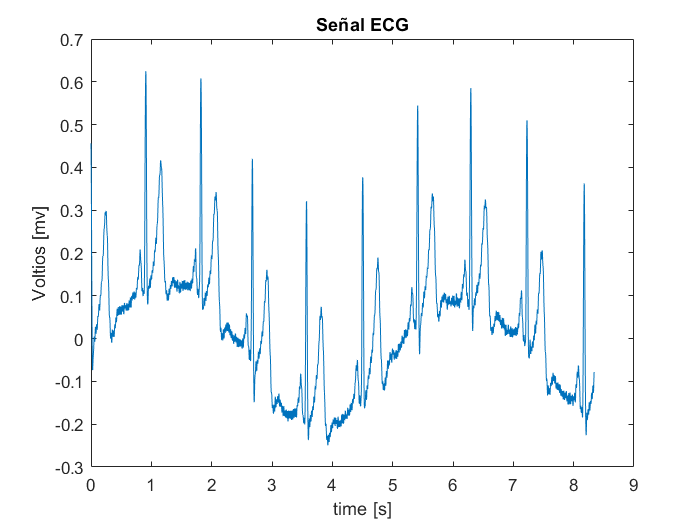

load('./ecg.mat') % cargar la matriz de la señal

%% inicialización de variables necesarias
Fs = 500;        %Frecuencia de muestreo
L = length(ecg); %Longitud de la señal
T = L/Fs;        %Duración de la señal


%vector entre 0 y 1/2 multiplicado por Fs
%vector entre 0 y Fs/2
f = Fs*(0:L/2)/L;

%vector de tiempo de 10000 elementos
t = linspace(0, T, L);
w = f*2*pi;             %vector omega, de frecuencias angulares
epsilon = 0.00000000001;

plot(t, ecg)
xlabel('time [s]')
ylabel('Voltios [mv]')
title('Señal ECG')

**Ahora analizaremos las componentes frecuenciales de la señal ECG**

*(note que la señal está aparentemente contaminada con un seno).*

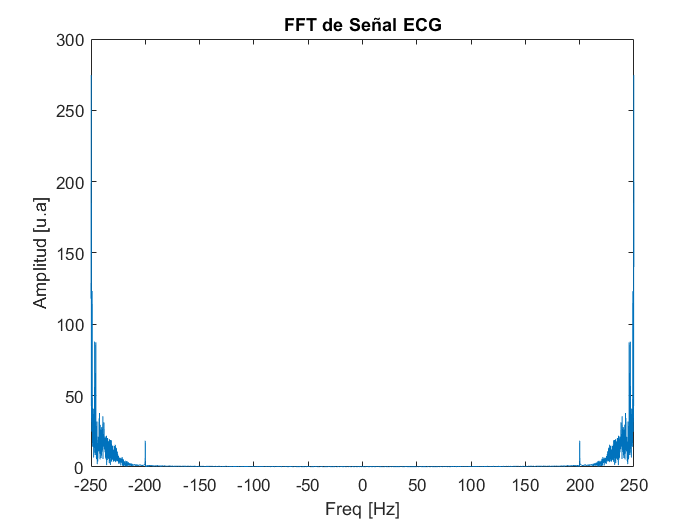

ecg_fft = fft(ecg)'; 
%Fxs = fftshift(ecg_fft); % Corrimiento de la transformada para obtener valores negativos y positivos. 
f = (-L/2:L/2-1)*Fs/L;


plot(f, abs( ecg_fft( 1: end) ));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT de Señal ECG');

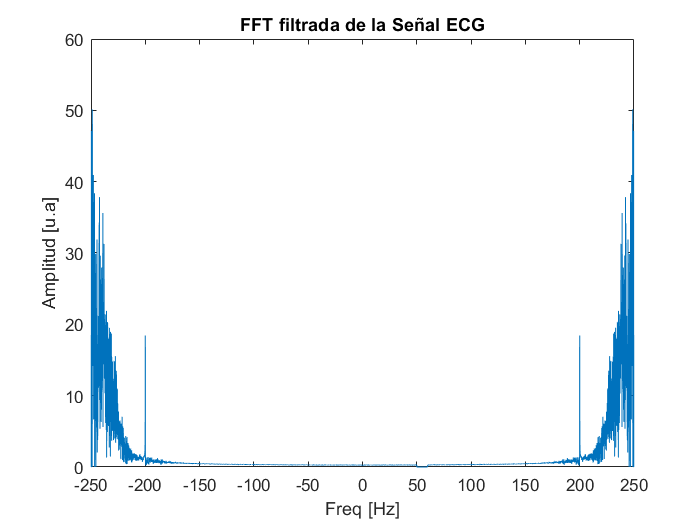

%ecg_fft( (f <= 20) & (f >= -20) ) = 0;
ecg_fft((f >= 50) & (f <= 60)) = 0;
%ecg_fft((f <= -50) & (f >= -60)) = 0;
%ecg_fft((f >= -200) & (f <= 200)) = 0;
%ecg_fft((f >= 1/4.5) & (f <= 1/5.5)) = 0;
ecg_fft(abs(ecg_fft) >= 80) = 0;

plot(f, abs( ecg_fft( 1: end) ));
xlabel('Freq [Hz]');
ylabel('Amplitud [u.a]');
title('FFT filtrada de la Señal ECG');

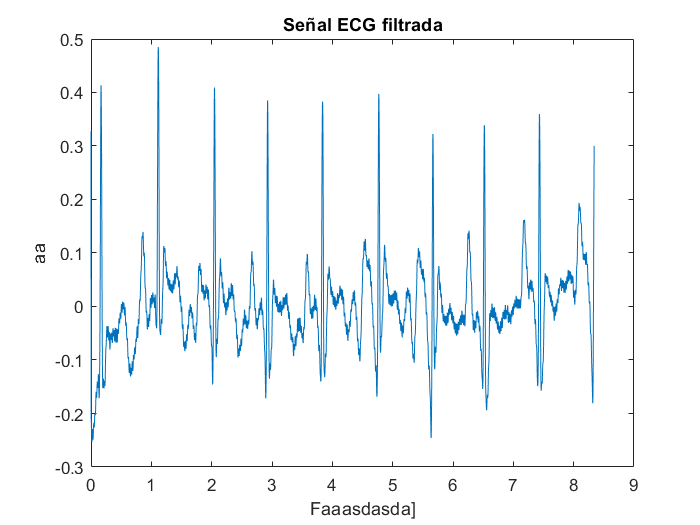

y_f = ifft(ecg_fft, 'Symmetric');

plot(t, y_f);
xlabel('Faaasdasda]');
ylabel('aa');
title('Señal ECG filtrada');